Load Data

% paths to data files being compared. change as necessary
hm_data_path = "Y:\usvi\stj\fishAuditing\HM_ST_comparison\HM_master_labels_TK\consolidated_data_HM_TK.txt";
st_data_path = "Y:\usvi\stj\fishAuditing\HM_ST_comparison\ST_master_labels_TK\consolidated_data_ST_TK.txt";

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
hm_raw = readtable(hm_data_path);
st_raw = readtable(st_data_path);


Total Annotations

Don't pay attention to this, use the excel version

% sites = categorical(["HM TK", "ST TK", "HM YA", "ST YA"]);
% calls = [3458, 2885, 2864, 2878];
% 
% figure(1); clf; hold on
% bar(sites, calls);
% xticklabels = ["HM TK", "ST TK", "HM YA", "ST YA"]

Create arrays with only one kind of call

- pick out just one type of call; put it into an array

- to be able to make the same kind of graph as the above block

hm_tonals = hm_raw(contains(hm_raw.Type, 'tonal'), :);
st_tonals = st_raw(contains(st_raw.Type, 'tonal'), :);

hm_pulses = hm_raw(contains(hm_raw.Type, 'pulse'), :);
st_pulses = st_raw(contains(st_raw.Type, 'pulse'), :);


Call Rate Over Time of Day

Yawzi -- Generate call rate data

% select which data you want call rates for (e.g. full set, pulses, tonals)
hm_data = hm_raw;
st_data = st_raw;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

hm_call_rates = zeros([1, 48]);
st_call_rates = zeros([1, 48]);
time_of_day = sort([0:10000:230000, 3000:10000:233000]);
i_time  = 1;
call_count = 0;

% go through HM data row by row to fill call rates matrix
for r = 1:height(hm_data)
    row = hm_data(r, :);
    time = time_of_day(i_time); % the minute we are looking at

    % check if that call is part of the same time and count it
    % note: currently only checking for time, not date or year
    if strcmp(row{1, 8}, 'boat')
        continue
    elseif time == row{1, 3} 
        call_count = call_count + 1;
    else
        % reset counters for next minute/half hour
        hm_call_rates(i_time) = call_count;
        call_count = 0;
        i_time = i_time + 1;
    end
end

hm_call_rates(i_time) = call_count; % fill in last datapoint
i_time = 1;

% go through ST data row by row to fill call rates matrix
for r = 1:height(st_data)
    row = st_data(r, :);
    time = time_of_day(i_time); % the minute we are looking at

    % check if that call is part of the same time and count it
    % note: currently only checking for time, not date or year
    if strcmp(row{1, 8}, 'boat')
        continue
    elseif time == row{1, 3} 
        call_count = call_count + 1;
    else
        % reset counters for next minute/half hour
        st_call_rates(i_time) = call_count;
        call_count = 0;
        i_time = i_time + 1;
    end
end

st_call_rates(i_time) = call_count;



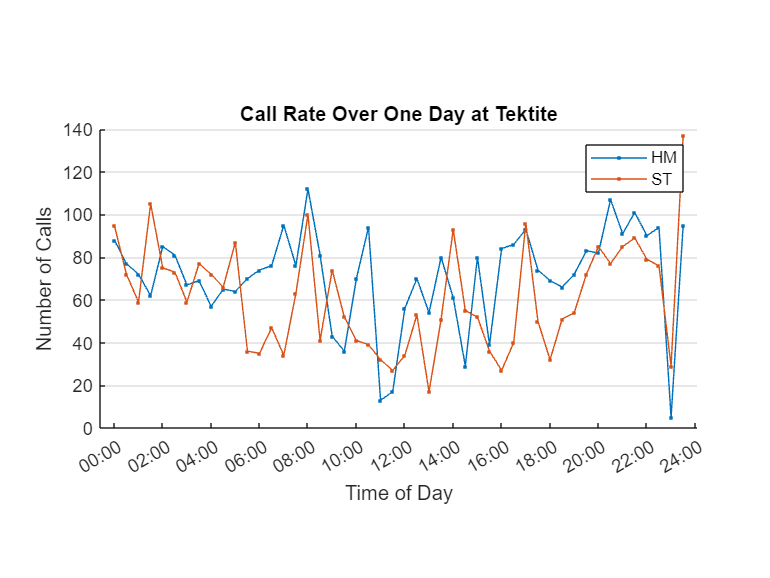

figure(1); clf; hold on

t = 0:hours(0.5):hours(23.5); % time of day array but in a nicer format

% use this block if you want to look at percentages rather than number
% (results in pretty similar data/trends)
% hm_call_rates_percent = hm_call_rates / height(hm_data);
% st_call_rates_percent = st_call_rates / height(st_data);

title('Call Rate Over One Day at Tektite'); % can change graph title

plot(t, hm_call_rates, '.-', 'DurationTickFormat','hh:mm');
plot(t, st_call_rates, '.-', 'DurationTickFormat','hh:mm');

xlabel('Time of Day');
ylabel('Number of Calls');
xticks(0:hours(2):hours(24));
set(gca, 'YGrid', 'on')
pbaspect([2 1 1]);
legend('HM', 'ST');